# **Projeto 2 - Mecânica dos Sólidos**

format short e

## **Aula 24:** Exercício 1

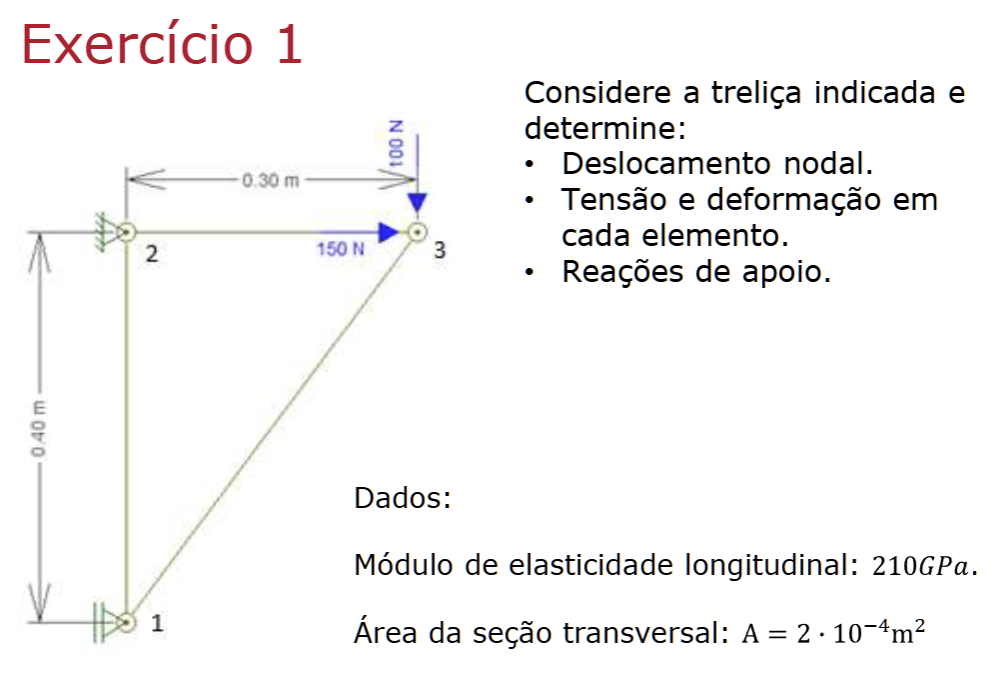

% PASSO 1: Definir a origem do sistema de referência e numerar os nós; elementos; GDL.

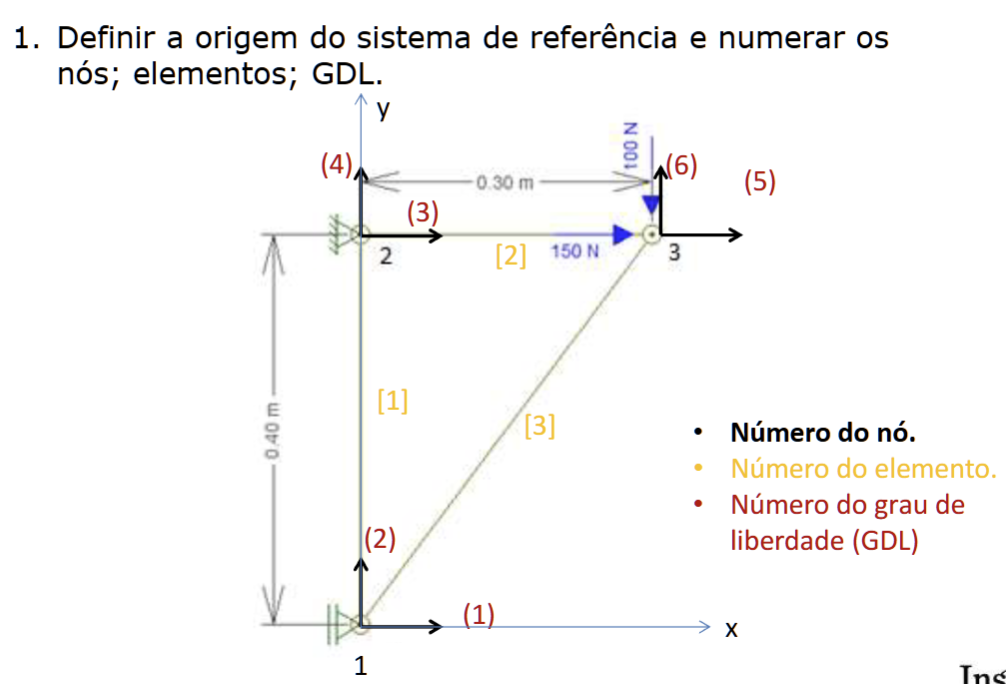

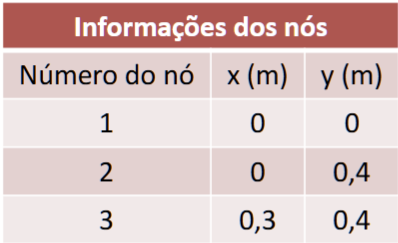

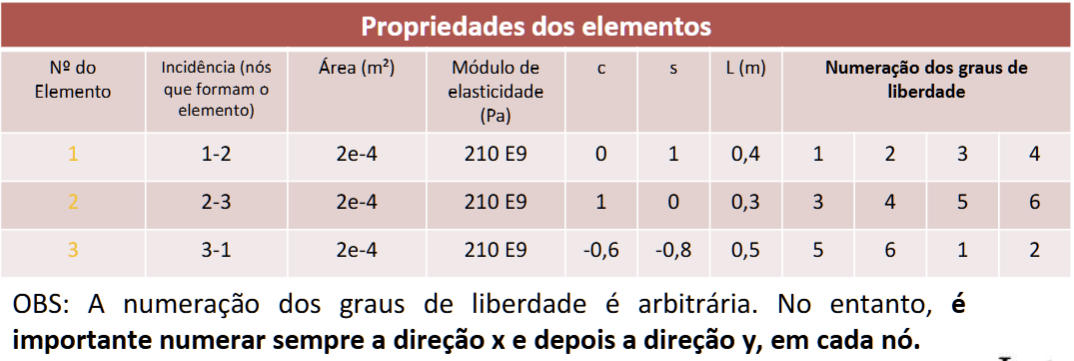

% PASSO 2: Montar a matriz de rigidez de cada elemento
E = 210 * 10^9; % Módulo de elasticidade longitudinal [Pa]
A = 2 * 10^(-4); % Área da seção transversal [m^2]
L = 5 % Metade do comprimento de um elemento

L =      5



num_elementos = 21;
num_nos = 13;

% X e Y de cada nó
%       x    y
x_y = [ 0,   0; % Nó 1
        L,   L*sqrt(3); % Nó 2 
        3*L,   L*sqrt(3); % Nó 3
        5*L,   L*sqrt(3); % Nó 4
        7*L,   L*sqrt(3); % Nó 5
        9*L,   L*sqrt(3); % Nó 6
        10*L,   0; % Nó 7
        9*L,   0; % Nó 8
        8*L,   0; % Nó 9
        6*L,   0; % Nó 10
        4*L,   0; % Nó 11
        2*L,   0; % Nó 12
        L,     0]; % Nó 13

% Matriz de incidências de cada elemento
incidencias = [
    1, 2; % Elemento 1
    2, 3; % Elemento 2
    3, 4; % Elemento 3
    4, 5; % Elemento 4
    5, 6; % Elemento 5
    6, 7; % Elemento 6
    7, 8; % Elemento 7
    8, 9; % Elemento 8
    6, 9; % Elemento 9
    5, 9; % Elemento 10
    9, 10; % Elemento 11
    5, 10; % Elemento 12
    4, 10; % Elemento 13
    10, 11; % Elemento 14
    4, 11; % Elemento 15
    3, 11; % Elemento 16
    11, 12; % Elemento 17
    3, 12; % Elemento 18
    2, 12; % Elemento 19
    12, 13; % Elemento 20
    13, 1; % Elemento 21
];
% ============================================================================

% Comprimento dos elementos (e)
len_elementos = zeros(length(x_y), 1);

% ============================================================================

% Cossenos (c) e senos (s)
%c1 = 0; s1 = 1;
%c2 = 1; s2 = 0;
%c3 = (x1 - x3)/l3; s3 = (y1 - y3)/l3;

cos_sen = zeros(length(x_y), 2);  % cos_sen_el = [ c, s; 
%                                                      ...]

% ============================================================================

% Matrizes de Rigidez de cada elemento (K1, K2, K3, ...)
K = cell(num_nos, 1);

% ============================================================================

% Calcular os comprimentos (L), os senos (s) e cossenos (c) e Matrizes de
% Rigidez (K)
for i = 1:num_elementos
    % Identificar os nós de cada elemento
    no1 = incidencias(i, 1);
    no2 = incidencias(i, 2);
    
    delta_x = x_y(no2,1) - x_y(no1,1);
    delta_y = x_y(no2,2) - x_y(no1,2);

    len_elementos(i) = sqrt(delta_x^2 + delta_y^2);   % tamanho elemento

    c = delta_x/len_elementos(i);                     % cosseno
    s = delta_y/len_elementos(i);                     % seno
    cos_sen(i,1) = c;
    cos_sen(i,2) = s;
    
    K{i} = [ c^2,   c*s, -c^2, -c*s;
             c*s,   s^2, -c*s, -s^2;
             -c^2, -c*s,  c^2,  c*s;
             -c*s, -s^2,  c*s,  s^2 ];
    K{i} = E*A/len_elementos(i) * K{i};
end
% K
% VERIFICAR SE OS CALCULOS DE SENO E COSSENO FUNCIONAM PARA TODOS OS
% ELEMENTOS, se tiver mais nos


% PASSO 3: Montar a matriz de rigidez global [Kg] da treliça fazendo asuperposição das matrizes dos elementos.
num_gdl = num_nos*2;
Kg = zeros(num_gdl, num_gdl);

for i = 1:num_nos
    K_elem = K{i};

    % Monta a matriz de Kg
    if i == num_nos
        nos = [2*i - 1, 2*i, 1, 2];
        for row = 1:4
            for col = 1:4
                Kg(nos(row), nos(col)) = Kg(nos(row), nos(col)) + K_elem(row, col);
            end
        end
    else 
        for row = 1:4      
            row_kg = (row + 2*(i-1));   % Se i = 1, comeca em 1, se i = 2 comeca em 3, etc ...
            for col = 1:4
                col_kg = (col + 2*(i-1));
                Kg(row_kg, col_kg) = Kg(row_kg, col_kg) + K_elem(row, col);
            end
        end
    end
end
Kg;
% Amo a notação do Matlab, simplesmente uma escadinha de end

% PASSO 4: Montar o vetor global de forças. No grau de liberdade com restrição deve aparecer um esforço de reação.
Pg = zeros(num_nos*2, 1);

% Vou adicionar manualmente, pq n tem como automatizar isso
% Pg(5) = 150;
% Pg(6) = -100;
Pg(3*2) = -300;      % R3y
Pg(5*2) = -300;      % R5y

Pg(8*2 - 1) = 0;     % R8x
Pg(8*2) = 0;         % R8y
Pg(13*2 - 1) = 0;    % R13x
Pg(13*2) = 0;        % R13y
Pg

Pg =      0
     0
     0
     0
     0
  -300
     0
     0
     0
  -300


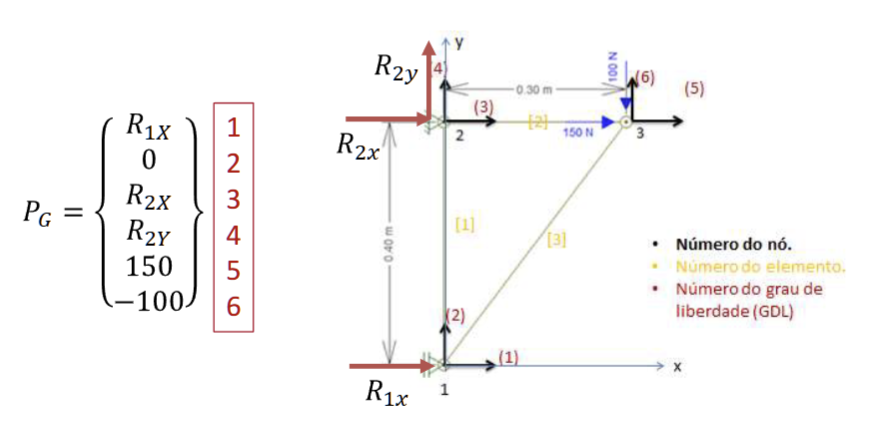

% PASSO 5: Aplicar as condições de contorno (eliminar linha e coluna do grau de liberdade com restrição)

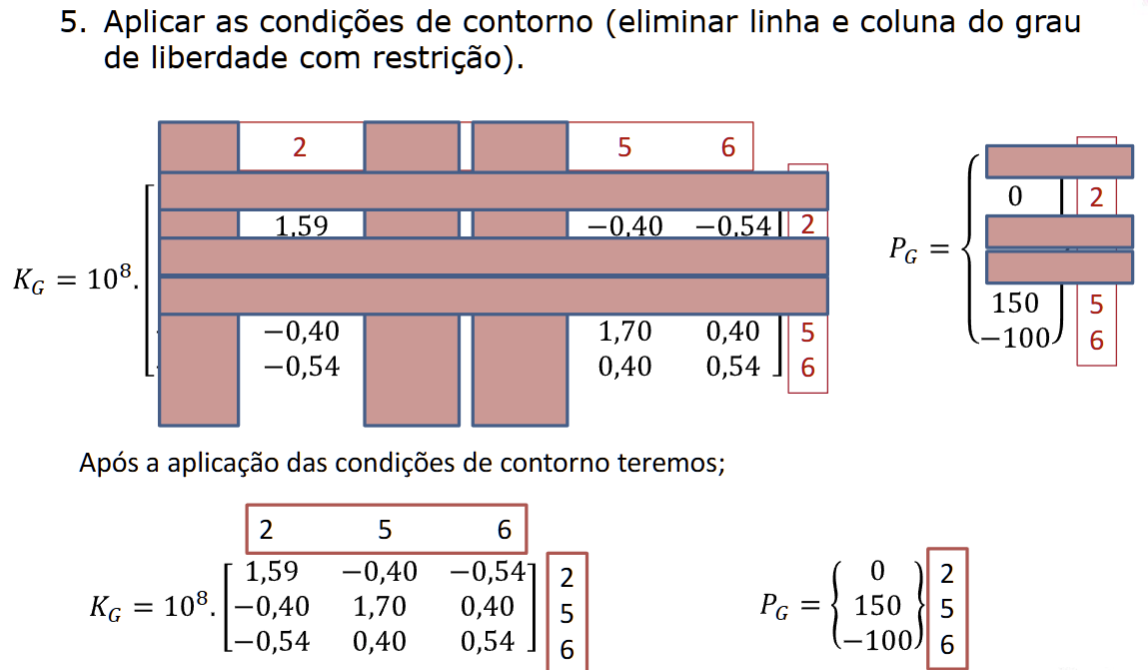

% Aplicando as condições de contorno temos:
Sem_restricao = [3*2, 5*2, 8*2 - 1, 8*2, 13*2 - 1, 13*2];
num_restri = length(Sem_restricao);

Kg_reduzida = zeros(num_restri, num_restri);
Pg_reduzida = zeros(num_restri, 1);

for i = 1:num_restri
    row = Sem_restricao(i);
    for j = 1:num_restri
        col = Sem_restricao(j);
        Kg_reduzida(i, j) = Kg(row, col);
    end

    Pg_reduzida(i, 1) = Pg(row,1);
end

Kg_reduzida

Kg_reduzida =             0            0            0            0            0            0
            0            0            0            0            0            0
            0            0   1.6800e+07            0            0            0
            0            0            0            0            0            0
            0            0            0            0   2.1000e+06            0
            0            0            0            0            0   6.3000e+06


Pg_reduzida

Pg_reduzida =   -300
  -300
     0
     0
     0
     0


% PASSO 6: Resolver o sistema de equações para a obtenção dos deslocamentos
%                      [Kg_reduzida] {U} = {Pg_reduzida}

U = linsolve(Kg_reduzida, Pg_reduzida);


U_expandida = zeros(num_nos*2, 1);

for row = 1:num_restri
    i = Sem_restricao(row);
    U_expandida(i) = U(row);
end
U_expandida

U_expandida =      0
     0
     0
     0
     0
   NaN
     0
     0
     0
   NaN


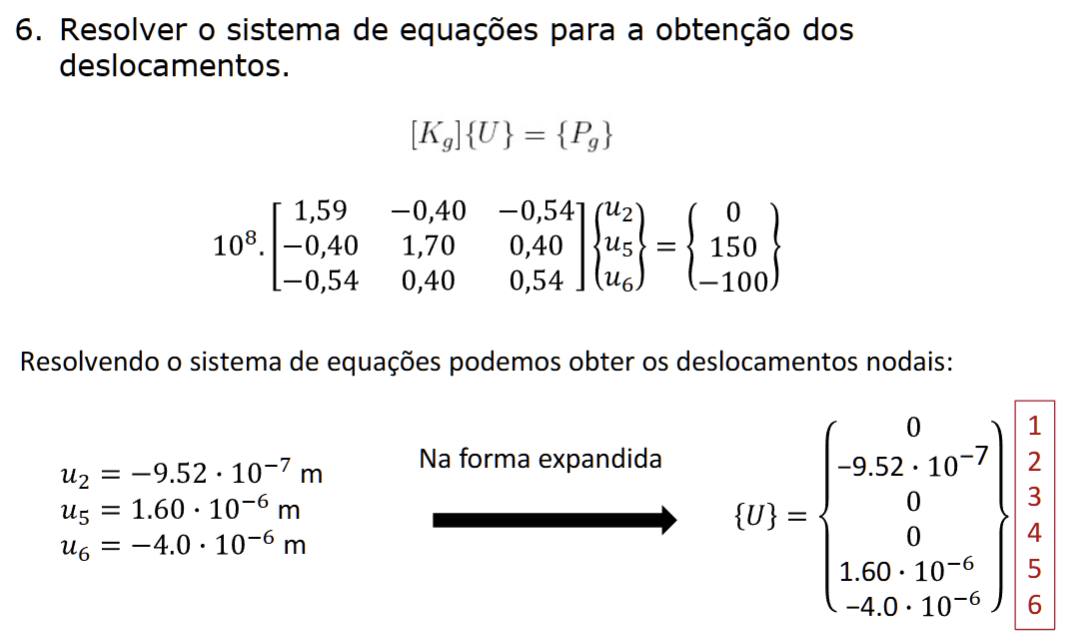

% PASSO 7: Determinar a deformação e a tensão em cada elemento.
deformacao = zeros(num_nos, 1);  % como cada nó tem 2 u's
tensao = zeros(num_nos, 1);  % como cada nó tem 2 u's

for i = 1:num_nos
    c = cos_sen(i,1);
    s = cos_sen(i,2);
    
    if i == num_nos
        aux = [U_expandida(2*i - 1);  U_expandida(2*i); U_expandida(1); U_expandida(2)];
    else
        index_u = (1 + 2*(i-1));
        aux = [U_expandida(index_u);  U_expandida(index_u+1); U_expandida(index_u+2); U_expandida(index_u+3)];
    end

    deformacao(i, 1) = (1/len_elementos(i,1)) * [-c, -s, c, s] * aux;
end

deformacao

deformacao =      0
   NaN
   NaN
   NaN
   NaN
     0
   NaN
   NaN
     0
     0


tensoes = E * deformacao

tensoes =      0
   NaN
   NaN
   NaN
   NaN
     0
   NaN
   NaN
     0
     0


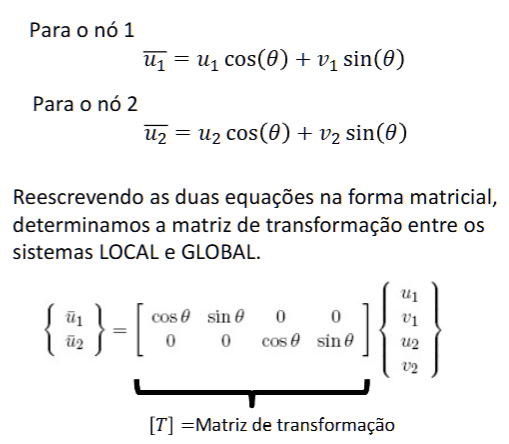

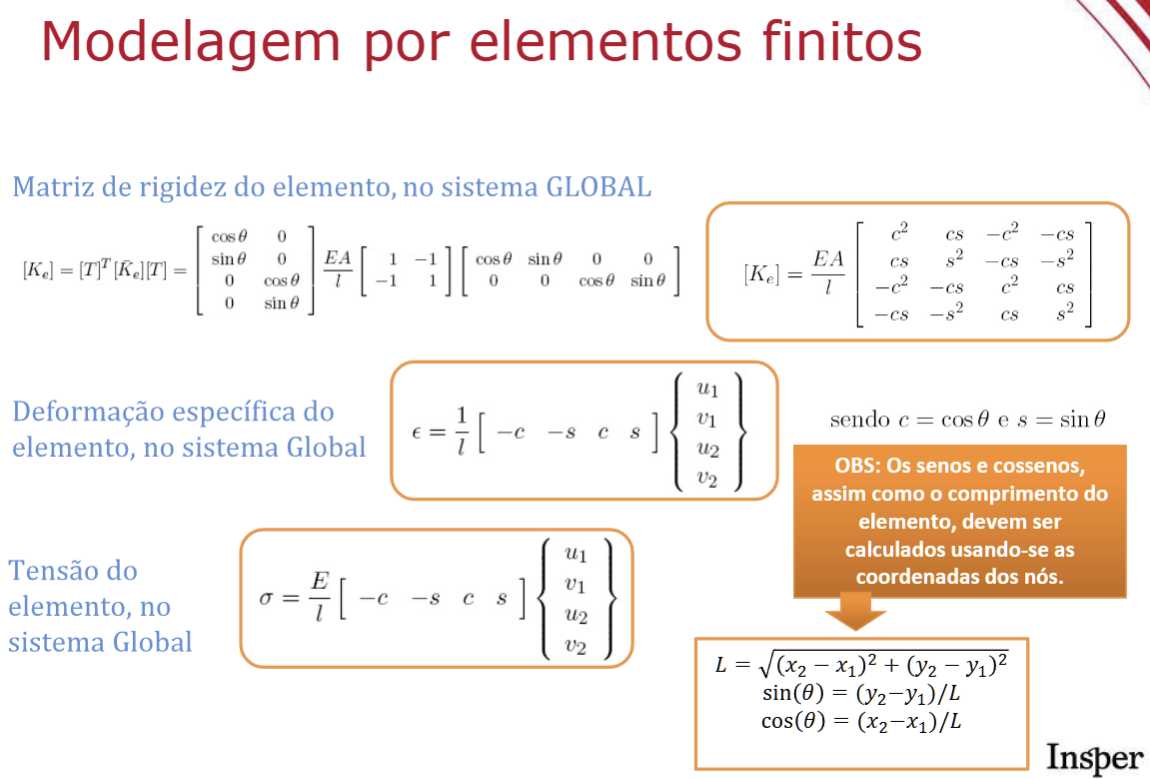

% PASSO 8: Determinar as reações de apoio nos nós com restrição.

Pg_final = Kg * U_expandida

Pg_final =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
